## 1. feladat

### Levezetés


$$\begin{array}{l}
f_1 +f_v \\
f_v \le f_2 -f_1 \\
\left(f_2 -f_1 \right)\cdot c_{\textrm{magic}} \\
c_{\textrm{magic}} \in \left\lbrack 0,1\right\rbrack \\
\Re \rightharpoondown \left\lbrack 0,1\right\rbrack 
\end{array}$$



$$\begin{array}{l}
f\left(n,i,f_1 ,f_2 \right)={10}^{\textrm{linspace}\left(\log_{10} \left(f_1 \right),\log_{10} \left(f_2 \right),n\right)\left\lbrack i\right\rbrack } \\
f\left(c,n,f_1 ,f_2 \right)={10}^{\log_{10} \left(f_1 \right)+\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
n\ge 0,n<c\\
f\left(c,n,f_1 ,f_2 \right)={{10}^{\log_{10} \left(f_1 \right)} \cdot 10}^{\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(f_2 \right)-\log_{10} \left(f_1 \right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(\frac{f_2 }{f_1 }\right)}{c-1}\cdot n} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\frac{\log_{10} \left(\frac{f_2 }{f_1 }\right)\cdot n}{c-1}} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{\log_{10} \left(\frac{f_2 }{f_1 }\right)\cdot n\cdot \frac{1}{c-1}} \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot 10}^{{\log_{10} \left(\frac{f_2 }{f_1 }\right)}^{\frac{n}{c-1}} } \\
f\left(c,n,f_1 ,f_2 \right)={f_1 \cdot \left(\frac{f_2 }{f_1 }\right)}^{\frac{n}{c-1}} 
\end{array}$$


### Ellenörzés

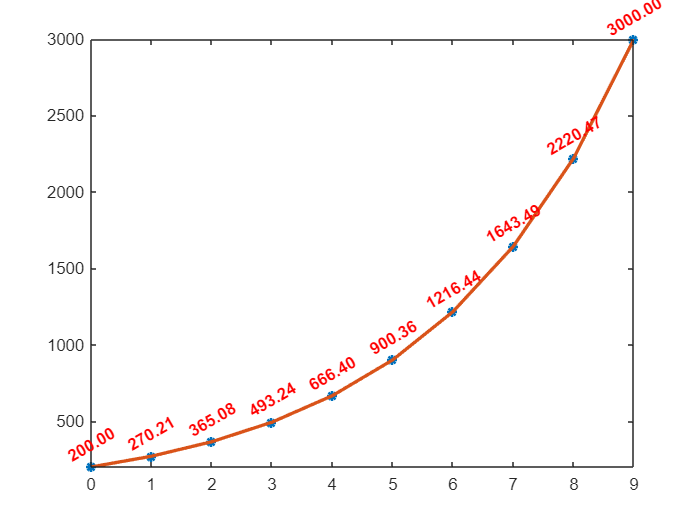

f_1 = 200;
f_2 = 3000;
count = 10;

t = 0:count-1;

f = @(c, n, f_1, f_2) f_1 .* (f_2/f_1) .^ (n / (c - 1));
fVals = f(count, t, f_1, f_2);

stem(t, fVals, "LineWidth", 1.5, "Marker","*", "LineStyle","none"); hold on;
plot(t, fVals, "LineWidth", 2);
ylim([200,3000]);

for k = 1 : length(fVals)
	textLabel = sprintf('%.2f', fVals(k));
	% Place text above the point by adding a little bit to the y value.
	text(k-1, fVals(k) + 150, textLabel, ...
		'HorizontalAlignment', 'center', ...
		'FontWeight', 'bold', ...
		'Color', 'r', ...
        'Rotation', 30);
end
hold off;

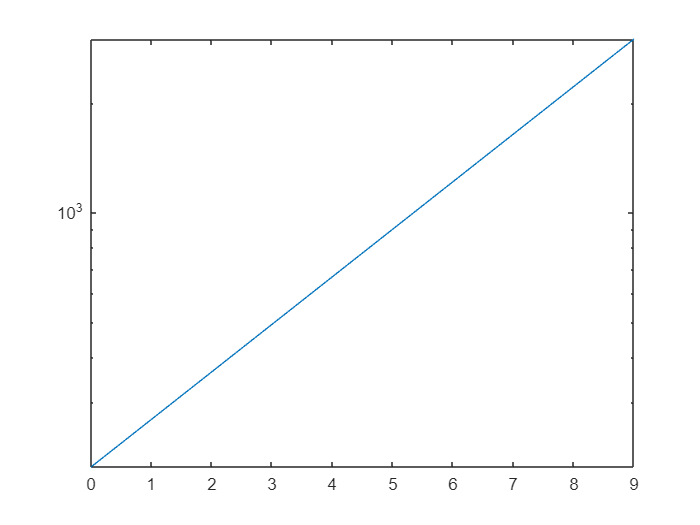

semilogy(t, fVals);

### Forrás

[világvége](https://github.com/compute-io/logspace/blob/master/lib/index.js)

## 2. feladat

C = 22 * 10 ^ (-9);
R = 10000;
f_p = 1 / (R * C * 2 * pi);
f_1 = 0.1 * f_p;
f_2 = 10 * f_p;
count = 21;

t = f(count, 0:count-1, f_1, f_2)

t = 1.0e+03 *

    0.0723    0.0911    0.1147    0.1443    0.1817    0.2288    0.2880    0.3626    0.4565    0.5746    0.7234    0.9107    1.1466    1.4434    1.8172    2.2877    2.8800    3.6257    4.5645    5.7464    7.2343


% feszültség csökkenés decibelben
a_db_f = [-0 -0.1 -0.1 -0.2 -0.3 -0.5 -0.7 -1 -1.5 -2.2 ...
    -3.1 -4 -5.4 -6.8 -8.6 -10.1 -11.8 -13.9 -15 -17.4 -19.9] 

a_db_f =          0   -0.1000   -0.1000   -0.2000   -0.3000   -0.5000   -0.7000   -1.0000   -1.5000   -2.2000   -3.1000   -4.0000   -5.4000   -6.8000   -8.6000  -10.1000  -11.8000  -13.9000  -15.0000  -17.4000  -19.9000


% eltolás fokban
fi_f = [-5.7 -7.1 -9 -11.2 -14.2 -17.5 -21.2 -26.2 -31.9 -37.8 ...
    -44.2 -50.1 -56.3 -61.9 -67.1 -70.8 -74.1 -77.3 -78.8 -81.2 -83.1] 

fi_f =    -5.7000   -7.1000   -9.0000  -11.2000  -14.2000  -17.5000  -21.2000  -26.2000  -31.9000  -37.8000  -44.2000  -50.1000  -56.3000  -61.9000  -67.1000  -70.8000  -74.1000  -77.3000  -78.8000  -81.2000  -83.1000


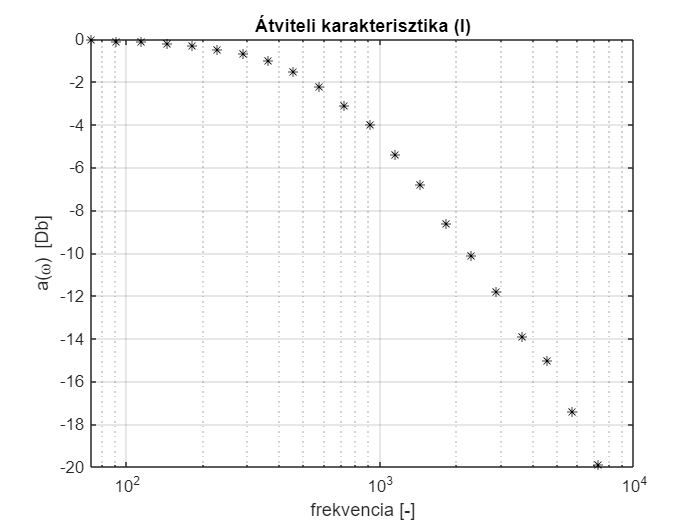



figure(); semilogx(t, a_db_f, "k*"); grid on;

xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");

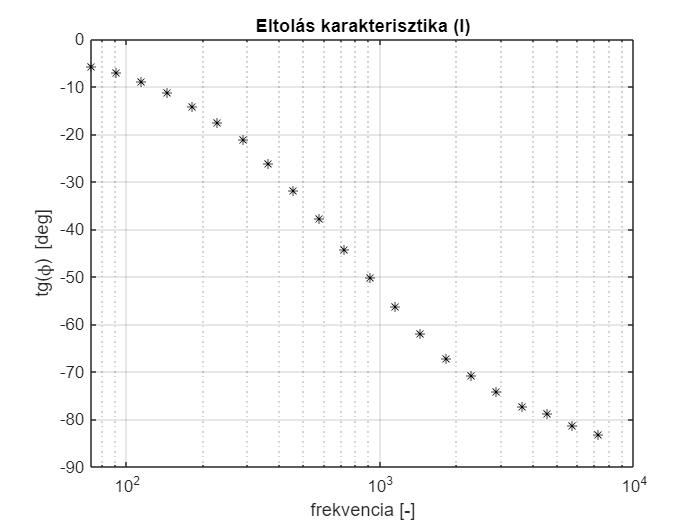


figure(); semilogx(t, fi_f, "k*"); grid on;
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");

## 7. feladat

% feszültség csökkenés decibelben
a_db_f = [-19.8 -17.9 -16.3 -14.1 -12.3 -10.4 -8.8 -7.1 -5.6 -4.3 ...
    -3.2 -2.3 -1.6 -1.1 -0.8 -0.5 -0.4 -0.2 -0.2 -0.1 -0.1] 

a_db_f =   -19.8000  -17.9000  -16.3000  -14.1000  -12.3000  -10.4000   -8.8000   -7.1000   -5.6000   -4.3000   -3.2000   -2.3000   -1.6000   -1.1000   -0.8000   -0.5000   -0.4000   -0.2000   -0.2000   -0.1000   -0.1000


% eltolás fokban
fi_f = [82.6 81.2 79.6 77.1 74.4 71 67 62.4 56.9 50.7 ...
    44.8 38.3 32.5 27.1 22.3 18.6 14.7 11.6 9.5 7.8 6.1] 

fi_f =    82.6000   81.2000   79.6000   77.1000   74.4000   71.0000   67.0000   62.4000   56.9000   50.7000   44.8000   38.3000   32.5000   27.1000   22.3000   18.6000   14.7000   11.6000    9.5000    7.8000    6.1000


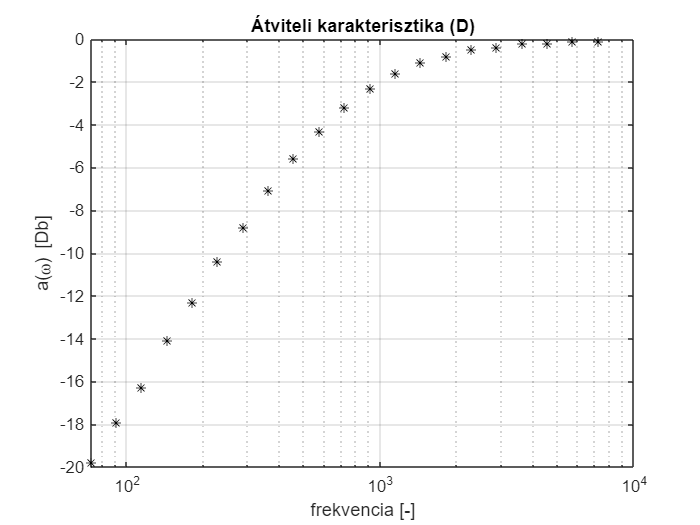



figure(); semilogx(t, a_db_f, "k*"); grid on;

xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (D)");

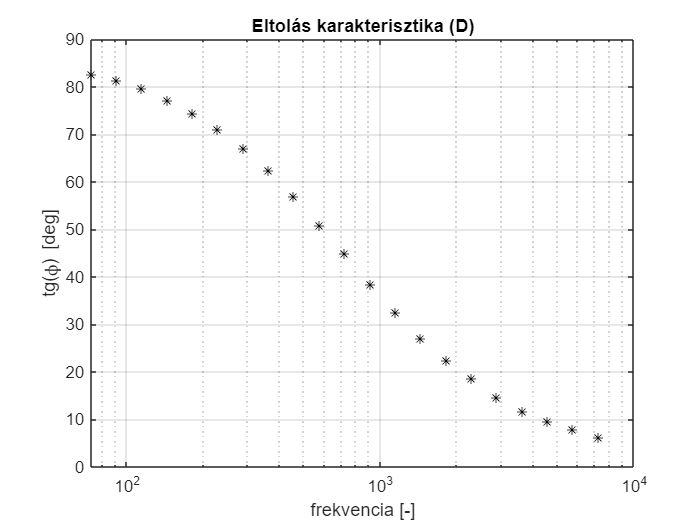


figure(); semilogx(t, fi_f, "k*"); grid on;
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (D)");